# Run Analysis on Synthetic Data

This notebook walks through a simplified version of the entire thesis. The idea is to create a dummy dataset to run the analysis - in the process of which we demonstrate how the analysis works. 

clear
close

### Setting up the experiment

In this section, we create an experiment object, in which we setup some parameters of the phantom data. One of the contributions of this paper is a table of $\lambda$ values that is parameterized on the number of fibers, the b-values, SNR and the order of the spherical harmonics model that's used. The $\lambda$ is computed per b-value (shell) and all of these parameters are stored in the `csaodfExperiment` object. 

simpleExpt = csaodfExperiment;
% Fill in parameters for voxels.
simpleExpt.fibers = 1;
simpleExpt.bvals  = [1000, 4000, 5000];
simpleExpt.SNR    = 50;
simpleExpt.order  = 4;

% Compute optimal regularization factor - lambda.
simpleExpt.computeLambda();

% Print experimentally computed weights for Laplace Beltrami regularization
simpleExpt.lambda

ans =     0.0009    0.0011    0.0022


### Generate synthetic data (from a phantom model)

% Create objects to hold gradient table
gTable = gradientTable;

Next, we create a gradient table. This can be generated and downloaded from [http://www.emmanuelcaruyer.com/WebApp/q-space-sampling.php?nbPoints=300&nbShells=3&alpha=2](http://www.emmanuelcaruyer.com/WebApp/q-space-sampling.php?nbPoints=300&nbShells=3&alpha=2) or, can be read from a pre-downloaded text file called '`samples3SH.txt`'.

gTable.readFromTxt('samples3SH.txt', simpleExpt.bvals);        

Now create synthetic data using some known orientations and angles to test if this kind of a reconstruction works. To keep things simple, we create a single voxel, with 300 samples computed in Q-space. We then attempt to reconstruct the spherical harmonic coefficients associated with these samples - depending on the order of the reconstruction used. We can view the points in Q-space using the show method.

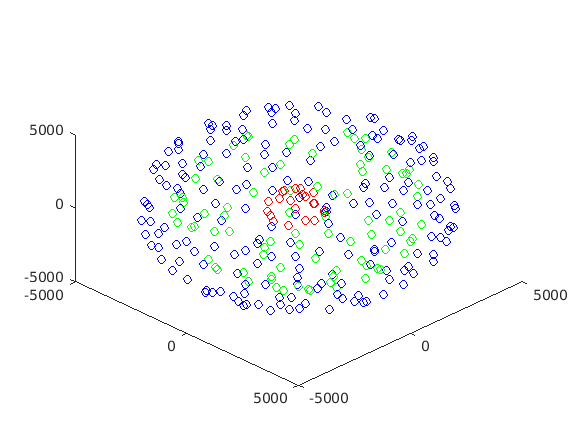

gTable.show()

% Create synthetic data.
diffusionData = createDiffusionData;
diffusionData.make(simpleExpt.fibers, gTable.bValues, simpleExpt.SNR, gTable.shellInd, gTable.table, pi/3);

% 'Load' it into a volume.
syntheticVolume = volume;
syntheticVolume.imageData(1,1,1,:) = diffusionData.data;

### Compute Spherical Harmonics transformation matrix

Using the gradient directions from the table above, we can then compute the spherical harmonics transformation matrix can be computed. The inputs necessary are the table and the order of the harmonics.

spHarmonicTform = sphericalHarmonicsMatrix(gTable.table, simpleExpt.order, 0);

### Process the volume!

Finally, we process the volume - meaning we reconstruct the spherical harmonics coefficients using the linear transformation we computed earlier, so that there's no need to do the full funk radon transform, thereby improving computation time by > 15x, and, also constructing a resonable estimation of the fiber orientation using a model-based method.

coeffVolume = simpleExpt.processVolume(syntheticVolume, gTable, spHarmonicTform);

Processing voxel (  1,  1,  1) ...................... Done!


### Visualize the reconstruction

To make more sense of how this looks like, we plot the Orientation Distribution Function and observe how it looks.

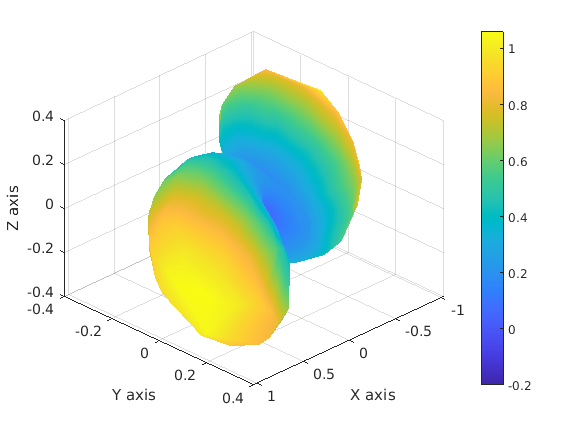

% Retrieve coefficients estimated.
coeffData = coeffVolume.dataAtVoxel(1,1,1,0,0);

% Choose a large number of uniform points for smoother visualization.
vizPoints = simpleExpt.genNSpherePoints(1000);

% Reconstruct data from coefficients - no lambda here.
shViz = sphericalHarmonicsMatrix(vizPoints, simpleExpt.order, 0);
reconstructedODF = shViz.coeffToSample(coeffData);

% Visualize reconstruction.
figure, 
simpleExpt.visualizeODF(reconstructedODF, vizPoints);